load("pomiary_3out.mat")

pomiary_3out =      1     2
     2     4
     5    -1


% pomiary_3out = load("../data/angle_data.txt")
size_data = size(pomiary_3out)

size_data =      3     2



t = 1:1:size_data(1);
y3= pomiary_3out(:,3) - pomiary_3out(1,3);

Index in position 2 exceeds array bounds. Index must not exceed 2.

plot(t, y3)

k3=(y3(300,1)-y3(1,1))/1.0;
tau3 = 31;
T3 = 69;
licz31 = [k3];
mian31 = [T3, 1];
[ld3,md3]=pade(tau3,1);

[l3,m3] = series(licz31,mian31,ld3,md3);
ym3 = step(l3,m3,t);
MSE3 = sum((y3-ym3).^2);

u = ones(size(y3));

y2ex = iddata(y3,u,1)

y2ex =

Time domain data set with 300 samples.
Sample time: 1 seconds                 
                                       
Outputs      Unit (if specified)       
   y1                                  
                                       
Inputs       Unit (if specified)       
   u1                                  
                                       


% compare(y2ex,y2mod,300)
% grid
% stepplot(y2mod)

y2mod = tf(l3, m3)

y2mod =
 
    -0.07414 s + 0.004783
  --------------------------
  69 s^2 + 5.452 s + 0.06452
 
Continuous-time transfer function.



[licz, mian] = tfdata(y2mod)

licz = 1×1 cell array
    {[0 -0.0741 0.0048]}


mian = 1×1 cell array
    {[69 5.4516 0.0645]}


licz = licz{1}

licz =          0   -0.0741    0.0048


mian = mian{1}

mian =    69.0000    5.4516    0.0645


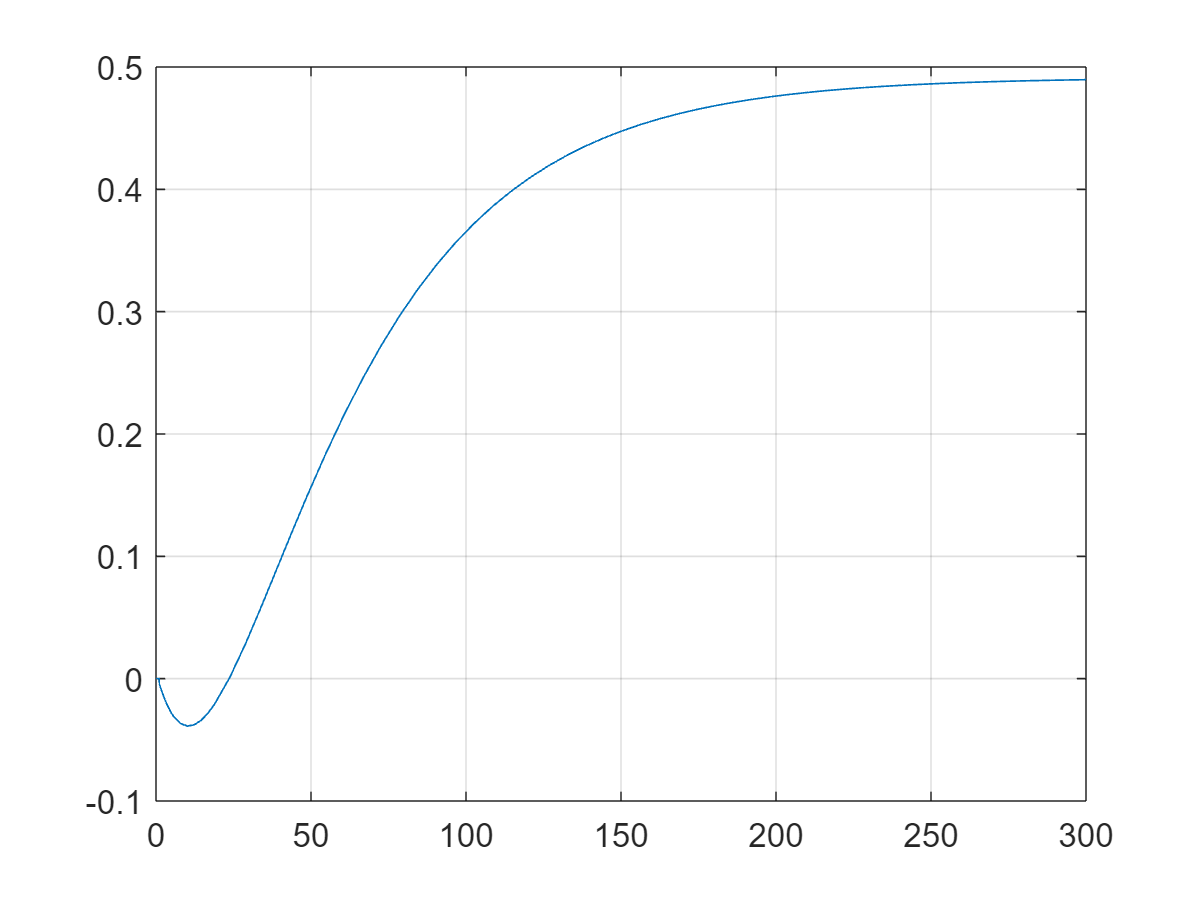


Kp = 3.3;
Ki = 0;
Kd = 4.2;
sim('model',300);
figure
plot(ans.ScopeData.time,ans.ScopeData.signals.values)
grid